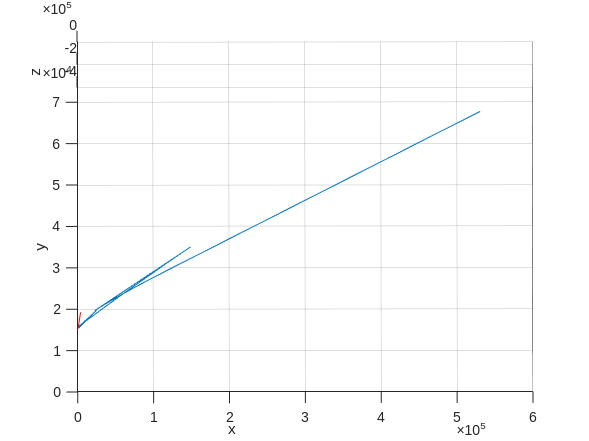

clear

tf = 10;
dt = 0.1;
t = 0:dt:tf;

r = nan(3, length(t));
v = nan(3, length(t));
a = nan(3, length(t));
u_n = nan(3, length(t));
rho = nan(1, length(t));

r(:, 1) = [250; 630; 430];
v(:, 1) = [90; 125; 170];
a(:, 1) = [16; 125; 30];
u_t = v(:, 1)/norm(v(:, 1));
u_b = cross(v(:, 1), a(:, 1))/norm(cross(v(:, 1), a(:, 1)));
u_n(:, 1) = cross(u_b, u_t);
a_n = dot(a(:, 1), u_n(:, 1));
rho(1) = dot(v(:, 1), v(:, 1))/a_n(:, 1);

for n = 1:length(t)-1
    a(:, n+1) = a(n); % Constant Acc.
    v(:, n+1) = v(:, n) + a(:, n+1)*dt;
    r(:, n+1) = r(:, n) + v(:, n)*dt + 0.5*a(:, n+1)*dt^2;
    u_t = v(:, n+1)/norm(v(:, n+1));
    u_b = cross(v(:, n+1), a(:, n+1))/norm(cross(v(:, n+1), a(:, n+1)));
    u_n(:, n+1) = cross(u_b, u_t);
    a_n = dot(a(:, n+1), u_n(:, n+1));
    rho(n+1) = dot(v(:, n+1), v(:, n+1))/a_n;
    
end

r_c = r + rho.*u_n;

% Plot
figure; hold on; grid on;
xlabel("x"); ylabel("y"); zlabel("z");
view(3);
plot3(r_c(1, :), r_c(2, :), r_c(3, :));
plot3(r(1, :), r(2, :), r(3, :), 'r');